clc 
clear
Simulink.sdi.clear
runTime=2.5; %Tiempo que dura la simulacion de Simulink

### Modelo de Planta

for Ts=0.03:0.005:0.06
    ts=Ts;
    %%Modelado
    s=tf('s');
    z=tf('z', Ts);
    Km=8.2897e-02;
    Tm= 6.0718e-02;
    Tf=0.18;
    P = Km/(Tm*s+1)/(Tf*s+1);
    Pd=c2d(P, Ts, 'zoh')

[zPd,pPd,kPd]=zpkdata(Pd,'v')
alfa=zPd(1);
Fd=(z-alfa)/(1-alfa)/z^2;
% Fd=Cd*Pd/(1+Cd*Pd) ==> Cd=Fd/Pd/(1-Fd)
Cd=minreal(Fd/Pd/(1-Fd));
Crd=Cd

Pd =
 
  0.002753 z + 0.002209
  ----------------------
  z^2 - 1.457 z + 0.5165
 
Sample time: 0.03 seconds
Discrete-time transfer function.



zPd = -0.8024

pPd =     0.8465
    0.6101


kPd = 0.0028

Crd =
 
  201.5 z^2 - 293.6 z + 104.1
  ---------------------------
    z^2 - 0.5548 z - 0.4452
 
Sample time: 0.03 seconds
Discrete-time transfer function.



Velocidad =    18.3000    0.0500         0         0
   18.3050    0.0500         0         0
   18.3100    0.0500         0         0
   18.3150    0.0500         0         0
   18.3200    0.0500         0         0
   18.3250    0.0500         0         0
   18.3300    0.0500         0         0
   18.3350    0.0500         0         0
   18.3400    0.0500         0         0
   18.3450    0.0500         0         0


result =          0
    0.0050
    0.0100
    0.0150
    0.0200
    0.0250
    0.0300
    0.0350
    0.0400
    0.0450


ans =          0
    0.0050
    0.0100
    0.0150
    0.0200
    0.0250
    0.0300
    0.0350
    0.0400
    0.0450


Pd =
 
  0.003619 z + 0.002799
  ----------------------
  z^2 - 1.385 z + 0.4626
 
Sample time: 0.035 seconds
Discrete-time transfer function.



zPd = -0.7735

pPd =     0.8233
    0.5619


kPd = 0.0036

Crd =
 
  155.8 z^2 - 215.8 z + 72.08
  ---------------------------
    z^2 - 0.5638 z - 0.4362
 
Sample time: 0.035 seconds
Discrete-time transfer function.



Velocidad =    18.3000    0.0500         0         0
   18.3050    0.0500         0         0
   18.3100    0.0500         0         0
   18.3150    0.0500         0         0
   18.3200    0.0500         0         0
   18.3250    0.0500         0         0
   18.3300    0.0500         0         0
   18.3350    0.0500         0         0
   18.3400    0.0500         0         0
   18.3450    0.0500         0         0


result =          0
    0.0050
    0.0100
    0.0150
    0.0200
    0.0250
    0.0300
    0.0350
    0.0400
    0.0450


ans =          0
    0.0050
    0.0100
    0.0150
    0.0200
    0.0250
    0.0300
    0.0350
    0.0400
    0.0450


Pd =
 
  0.004566 z + 0.003405
  ----------------------
  z^2 - 1.318 z + 0.4144
 
Sample time: 0.04 seconds
Discrete-time transfer function.



zPd = -0.7457

pPd =     0.8007
    0.5175


kPd = 0.0046

Crd =
 
  125.5 z^2 - 165.4 z + 51.99
  ---------------------------
    z^2 - 0.5728 z - 0.4272
 
Sample time: 0.04 seconds
Discrete-time transfer function.



Velocidad =    18.3000    0.0500         0         0
   18.3050    0.0500         0         0
   18.3100    0.0500         0         0
   18.3150    0.0500         0         0
   18.3200    0.0500         0         0
   18.3250    0.0500         0         0
   18.3300    0.0500         0         0
   18.3350    0.0500         0         0
   18.3400    0.0500         0         0
   18.3450    0.0500         0         0


result =          0
    0.0050
    0.0100
    0.0150
    0.0200
    0.0250
    0.0300
    0.0350
    0.0400
    0.0450


ans =          0
    0.0050
    0.0100
    0.0150
    0.0200
    0.0250
    0.0300
    0.0350
    0.0400
    0.0450


Pd =
 
  0.005584 z + 0.004014
  ----------------------
  z^2 - 1.255 z + 0.3712
 
Sample time: 0.045 seconds
Discrete-time transfer function.



zPd = -0.7189

pPd =     0.7788
    0.4766


kPd = 0.0056

Crd =
 
  104.2 z^2 - 130.8 z + 38.67
  ---------------------------
    z^2 - 0.5818 z - 0.4182
 
Sample time: 0.045 seconds
Discrete-time transfer function.



Velocidad =    18.3000    0.0500         0         0
   18.3050    0.0500         0         0
   18.3100    0.0500         0         0
   18.3150    0.0500         0         0
   18.3200    0.0500         0         0
   18.3250    0.0500         0         0
   18.3300    0.0500         0         0
   18.3350    0.0500         0         0
   18.3400    0.0500         0         0
   18.3450    0.0500         0         0


result =          0
    0.0050
    0.0100
    0.0150
    0.0200
    0.0250
    0.0300
    0.0350
    0.0400
    0.0450


ans =          0
    0.0050
    0.0100
    0.0150
    0.0200
    0.0250
    0.0300
    0.0350
    0.0400
    0.0450


Pd =
 
  0.006663 z + 0.004618
  ----------------------
  z^2 - 1.196 z + 0.3325
 
Sample time: 0.05 seconds
Discrete-time transfer function.



zPd = -0.6931

pPd =     0.7575
    0.4389


kPd = 0.0067

Crd =
 
  88.64 z^2 - 106.1 z + 29.47
  ---------------------------
    z^2 - 0.5906 z - 0.4094
 
Sample time: 0.05 seconds
Discrete-time transfer function.



Velocidad =    18.3000    0.0500         0         0
   18.3050    0.0500         0         0
   18.3100    0.0500         0         0
   18.3150    0.0500         0         0
   18.3200    0.0500         0         0
   18.3250    0.0500         0         0
   18.3300    0.0500         0         0
   18.3350    0.0500         0         0
   18.3400    0.0500         0         0
   18.3450    0.0500         0         0


result =          0
    0.0050
    0.0100
    0.0150
    0.0200
    0.0250
    0.0300
    0.0350
    0.0400
    0.0450


ans =          0
    0.0050
    0.0100
    0.0150
    0.0200
    0.0250
    0.0300
    0.0350
    0.0400
    0.0450


Pd =
 
  0.007795 z + 0.005209
  ----------------------
  z^2 - 1.141 z + 0.2978
 
Sample time: 0.055 seconds
Discrete-time transfer function.



zPd = -0.6682

pPd =     0.7367
    0.4042


kPd = 0.0078

Crd =
 
  76.9 z^2 - 87.74 z + 22.9
  -------------------------
   z^2 - 0.5994 z - 0.4006
 
Sample time: 0.055 seconds
Discrete-time transfer function.



Velocidad =    18.3000    0.0500         0         0
   18.3050    0.0500         0         0
   18.3100    0.0500         0         0
   18.3150    0.0500         0         0
   18.3200    0.0500         0         0
   18.3250    0.0500         0         0
   18.3300    0.0500         0         0
   18.3350    0.0500         0         0
   18.3400    0.0500         0         0
   18.3450    0.0500         0         0


result =          0
    0.0050
    0.0100
    0.0150
    0.0200
    0.0250
    0.0300
    0.0350
    0.0400
    0.0450


ans =          0
    0.0050
    0.0100
    0.0150
    0.0200
    0.0250
    0.0300
    0.0350
    0.0400
    0.0450


Pd =
 
   0.008971 z + 0.00578
  ----------------------
  z^2 - 1.089 z + 0.2667
 
Sample time: 0.06 seconds
Discrete-time transfer function.



zPd = -0.6443

pPd =     0.7165
    0.3723


kPd = 0.0090

Crd =
 
  67.79 z^2 - 73.81 z + 18.08
  ---------------------------
    z^2 - 0.6082 z - 0.3918
 
Sample time: 0.06 seconds
Discrete-time transfer function.



Velocidad =    18.3000    0.0500         0         0
   18.3050    0.0500         0         0
   18.3100    0.0500         0         0
   18.3150    0.0500         0         0
   18.3200    0.0500         0         0
   18.3250    0.0500         0         0
   18.3300    0.0500         0         0
   18.3350    0.0500         0         0
   18.3400    0.0500         0         0
   18.3450    0.0500         0         0


result =          0
    0.0050
    0.0100
    0.0150
    0.0200
    0.0250
    0.0300
    0.0350
    0.0400
    0.0450


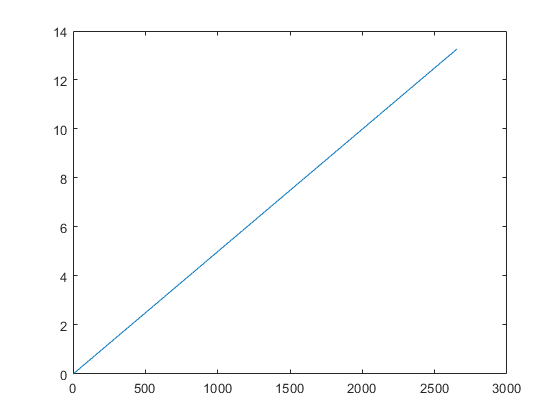

ans =          0
    0.0050
    0.0100
    0.0150
    0.0200
    0.0250
    0.0300
    0.0350
    0.0400
    0.0450


    load v_Velocidad_rampa.mat Velocidad
    Velocidad = Velocidad(3500:6029,:)
    PlotSimulation("Ts:"+Ts,"SIM_VELOCIDAD.slx")
end

## El mejor es Ts=0.15